Chargement des images

imread("img/Corn__Cercospora_leaf_spot Gray_leaf_spot/0a01cc10-3892-4311-9c48-0ac6ab3c7c43___RS_GLSp 9352.JPG" )

ans = 256×256×3 uint8 array
ans(:,:,1) =

   190   165   181   207   201   199   203   188   199   177   180   161   169   171   165   196   192   166    67    53    68    75    67    72    73    74    75    77    81    81    80    79    81    81    92    87    91    95    98   129   140   125   106    85    68    52    48    53    54    56    59    58    55    56    61    66    82    79    74    65    57    51    52    51    53    58    46    41    49    42    40    61    60    44    56    34    44   152   169   151   144   145   146   189   192   195   191   178   168   196   189   173   196   192   167   187   176   198   177   174   198   202   193   174   163   181   189   143   180   196   181   182   161   141   129   158   158   159   139   171   164   147    96   120   168   152   131   118   123   117   134   132   129   139   128   118   132   173   193   157   153   190   184   160   183   188   182   172   151   178   171   185   206   193   172   188   208   167   188   1

## Adaptation du réseau neuronal 

net = googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


lay = net.Layers

lay =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution                  

inLayer = lay(1)

inLayer =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inSize = inLayer.InputSize

inSize =    224   224     3


lgraph = layerGraph(net);
newFc = fullyConnectedLayer(4,"Name","new_fc");
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newOut = classificationLayer("Name","new_out");
lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Image datastores

imds = imageDatastore("img", "IncludeSubfolders",true, "LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\00120a18-ff90-46e4-92fb-2b7a10345bd3___RS_GLSp 9357_270deg.JPG';
                              ' ...00120a18-ff90-46e4-92fb-2b7a10345bd3___RS_GLSp 9357_new30degFlipLR.JPG';
                              ' ...\00a20f6f-e8bd-4453-9e25-36ea70feb626___RS_GLSp 4655.JPG'
                               ... and 7313 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img'
                              }
                      Labels: [Corn__Cercospora_leaf_spot Gray_leaf_spot; Corn__Cercospora_leaf_spot Gray_leaf_spot; Corn__Cercospora_leaf_spot Gray_leaf_spot ... and 7313 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"

imds.Labels

ans = 7316×1 categorical array
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn

[trainAllImgs, testAllImgs] = splitEachLabel(imds, 0.7, "randomized")

trainAllImgs =   ImageDatastore with properties:

                       Files: {
                              ' ...\00a20f6f-e8bd-4453-9e25-36ea70feb626___RS_GLSp 4655.JPG';
                              ' ...\00a20f6f-e8bd-4453-9e25-36ea70feb626___RS_GLSp 4655_90deg.JPG';
                              ' ...00a20f6f-e8bd-4453-9e25-36ea70feb626___RS_GLSp 4655_new30degFlipLR.JPG'
                               ... and 5118 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img'
                              }
                      Labels: [Corn__Cercospora_leaf_spot Gray_leaf_spot; Corn__Cercospora_leaf_spot Gray_leaf_spot; Corn__Cercospora_leaf_spot Gray_leaf_spot ... and 5118 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"   

testAllImgs =   ImageDatastore with properties:

                       Files: {
                              ' ...\00120a18-ff90-46e4-92fb-2b7a10345bd3___RS_GLSp 9357_270deg.JPG';
                              ' ...00120a18-ff90-46e4-92fb-2b7a10345bd3___RS_GLSp 9357_new30degFlipLR.JPG';
                              ' ...\00a20f6f-e8bd-4453-9e25-36ea70feb626___RS_GLSp 4655_270deg.JPG'
                               ... and 2192 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img'
                              }
                      Labels: [Corn__Cercospora_leaf_spot Gray_leaf_spot; Corn__Cercospora_leaf_spot Gray_leaf_spot; Corn__Cercospora_leaf_spot Gray_leaf_spot ... and 2192 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "

pour travailler sur une partie des images et pas sur la totalité

nFiles = length(trainAllImgs.Files);
RandIndices = randperm(nFiles);
%nSixtyPercent = round(0.6*nFiles);
indices = RandIndices(1:500)

indices =         2004        3302         821        4817         426         312        2596        1442        4223        4015        3465        3667        2516        3962        4371        1123        1763          11        2165        1773        1571         128        1895        3765        1413        3430        1421        3586        2692        1696        3598        2751         136         941        2794        4356        3195        3655        1443         824        1481        3720        1994        3180         612        4502          61        3271         654        1075


trainPartImg = subset(trainAllImgs,indices)

trainPartImg =   ImageDatastore with properties:

                       Files: {
                              ' ...\Matlab\SI-IA-PlantDiseases\img\Corn__Common_rust\RS_Rust 2339.JPG';
                              ' ...\b20f5280-a83b-46c0-a611-0febe7199789___RS_NLB 4038_180deg.JPG';
                              ' ...\bbde9366-ec3c-4354-815b-5b95b6cdb676___RS_GLSp 4481.JPG'
                               ... and 497 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img'
                              }
                      Labels: [Corn__Common_rust; Corn__Northern_Leaf_Blight; Corn__Cercospora_leaf_spot Gray_leaf_spot ... and 497 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultO

trainPartImg.Files

ans = 500×1 cell array
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img\Corn__Common_rust\RS_Rust 2339.JPG'                                                                              }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img\Corn__Northern_Leaf_Blight\b20f5280-a83b-46c0-a611-0febe7199789___RS_NLB 4038_180deg.JPG'                        }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img\Corn__Cercospora_leaf_spot Gray_leaf_spot\bbde9366-ec3c-4354-815b-5b95b6cdb676___RS_GLSp 4481.JPG'               }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img\Corn__healthy\bd387a28-3b26-47d8-827b-062ae0a0f234___R.S_HL 7990 copy 2_flipLR.jpg'                              }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img\Corn__Cercospora_leaf_spot Gray_leaf_spot\671065f1-731f-45fa-9c11-3e0080f79ff3___RS_GLSp 4344.JPG'               }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img\Corn__Cercospora_leaf_spot Gray_leaf_spot\4baea4d9-8343-4550-838f-86dfb7672591___RS_GLSp 4

nFiles = length(testAllImgs.Files);
RandIndices = randperm(nFiles);
indices = RandIndices(1:200)

indices =          256        1864        1048        1085         761        1095        1304         698         269           8         448         823        1326        1243        1820         498        2161        1345        2006        1121         462         988         443        1979        1733         735         685          20         428         138        1302        1443         712         488        2020         371         696         514         129         888        1652         866          37        1976          87         563        1854         639         419         184


testPartImg  = subset (testAllImgs, indices)

testPartImg =   ImageDatastore with properties:

                       Files: {
                              ' ...\94dbcd4e-5fc8-47d6-a944-dc0cc7c6ead5___RS_GLSp 4638 copy.jpg';
                              ' ...\6aa92f1b-d5bd-4dcc-a130-925034576462___R.S_HL 8071 copy 2_flipLR.jpg';
                              ' ...\Matlab\SI-IA-PlantDiseases\img\Corn__Common_rust\RS_Rust 2738.JPG'
                               ... and 197 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img'
                              }
                      Labels: [Corn__Cercospora_leaf_spot Gray_leaf_spot; Corn__healthy; Corn__Common_rust ... and 197 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOut

trainds = augmentedImageDatastore([224 224],trainPartImg);
testds = augmentedImageDatastore([224 224],testPartImg);

## Entraînement du réseau

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:10 |       18.75% |       2.7273 |          0.0010 |
|       8 |          50 |       00:06:03 |       96.88% |       0.0576 |          0.0010 |
|      10 |          70 |       00:08:22 |       96.88% |       0.1505 |          0.0010 |
|========================================================================================|


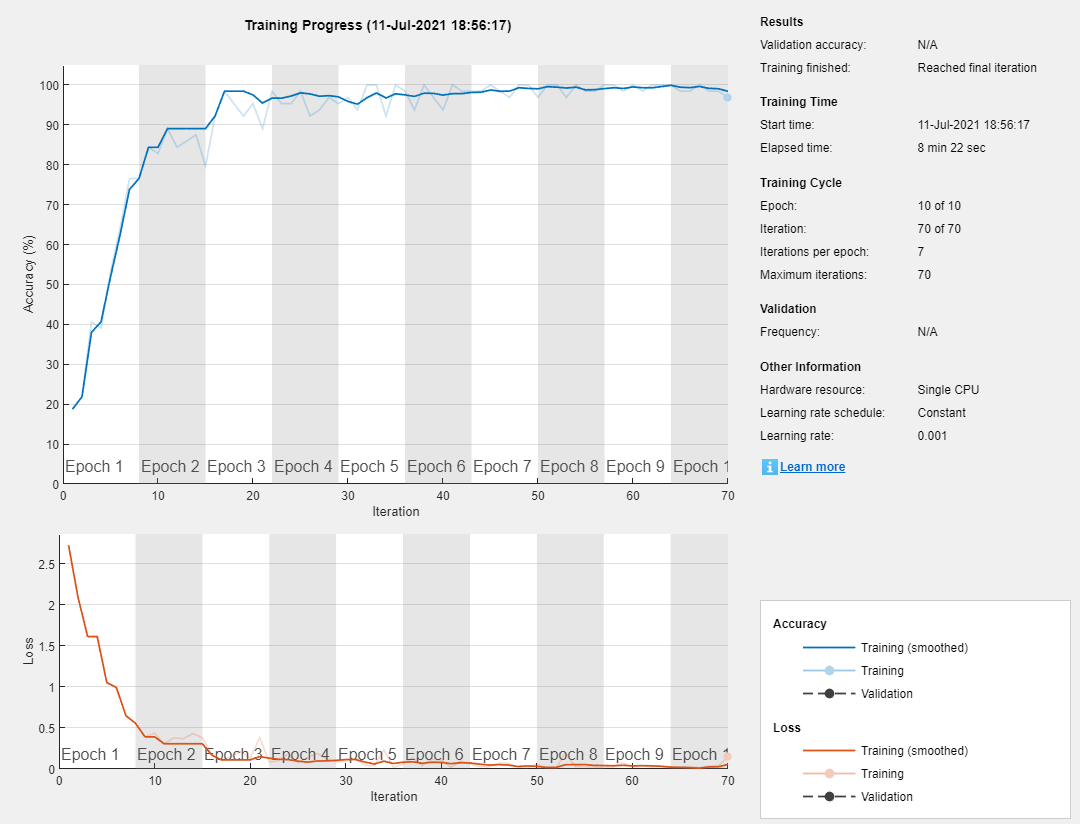

plantnetcorn =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


options = trainingOptions("sgdm",...
    'InitialLearnRate', 0.001, ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'MaxEpochs',10, ...
    'MiniBatchSize',64, ...
    'Plots','training-progress',...
    'Shuffle','every-epoch');
    
plantnetcorn = trainNetwork(trainds,lgraph,options)

save plantnetcorn

## Evaluation du réseau sur les données de test

predictions = classify(plantnetcorn,testds)

predictions = 200×1 categorical array
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__healthy 
     Corn__Common_rust 
     Corn__Northern_Leaf_Blight 
     Corn__Common_rust 
     Corn__Northern_Leaf_Blight 
     Corn__Northern_Leaf_Blight 
     Corn__Common_rust 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Common_rust 
     Corn__Northern_Leaf_Blight 
     Corn__Northern_Leaf_Blight 
     Corn__healthy 
     Corn__Common_rust 
     Corn__healthy 
     Corn__Northern_Leaf_Blight 
     Corn__healthy 
     Corn__Northern_Leaf_Blight 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Common_rust 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__healthy 
     Corn__healthy 
     Corn__Common_rust 
     Corn__Common_rust 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gray_leaf_spot 
     Corn__Cercospora_leaf_spot Gra

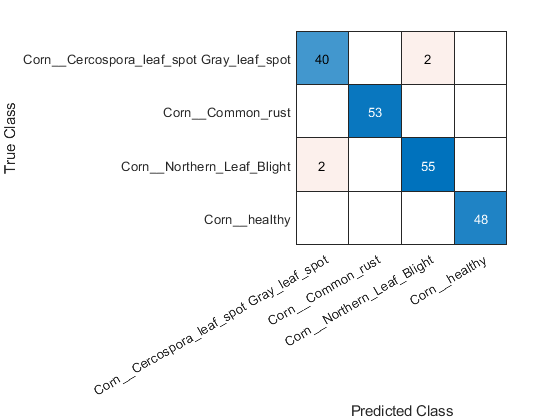

confusionchart(testPartImg.Labels, predictions)

## Temps d'exécution sur une image

load plantnetcorn.mat

net = plantnetcorn

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


img = imread("corn-healthy.jpg" );
img = imresize(img, [224,224]);
tic
label = classify (plantnetcorn,img)

label = categorical
     Corn__healthy 


toc

Elapsed time is 1.398943 seconds.
